clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)

imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files=dir(label_directory)

labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


imgs = zeros(512,512,3,18,'uint8');
labels = zeros(512,512,3,18,'uint8');
for i=3:20
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)

ans =    512   512     3    18


size(labels)

ans =    512   512     3    18


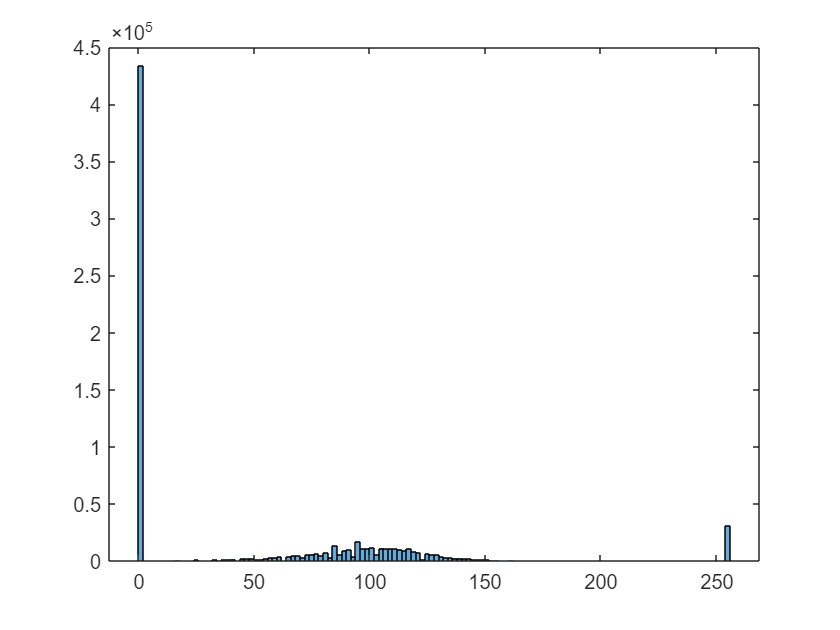


img_2 = imgs(:,:,:,2);
label_2 = labels(:,:,:,2);

% Extract colour channels
R_2 = img_2(:,:,1); % Red CH
G_2 = img_2(:,:,2); % Green CH
B_2 = img_2(:,:,3); % Blue CH

% Enhance G plane contrast
G_2_eq = histeq(G_2);
img_2_enhance_g = img_2;
img_2_enhance_g(:,:,2) = G_2_eq;

% Apply quant to reduce #CH of unique green values
levels = 1; % Controll blockiness (higher = smoother)
quant = 256 / levels;
G_2_quantized = round(G_2_eq / quant) * quant;
img_2_green_quant = img_2;
img_2_green_quant(:,:,2) = G_2_quantized; % Replace green channel w/ quantised version

% Preserve sharp edges whilst removing (most) green
img_2_gray = rgb2gray(img_2_green_quant); % Convert to grayscale
im_2_edges = edge(img_2_gray,'Canny'); % Detect edges

G_2_quant = img_2_green_quant(:,:,2); % Create G plane mask
green_mask = (G_2_quant > 0.5 * img_2_green_quant(:,:,1)) & (G_2_quant> 1.1 * img_2_green_quant(:,:,3)) & (G_2_quant > 200);

green_mask(im_2_edges) = 0; % Preserve edges (keep intact) whilst removing G plane
img_2_no_green = img_2_green_quant;
img_2_no_green(repmat(green_mask, [1,1,3])) = 0; 

histogram(img_2_no_green);

img_2_thresh = img_2_no_green;
img_2_thresh(img_2_thresh<250) = 0;
img_2_inv = 255 - img_2_thresh

img_2_inv = 512×512×3 uint8 array
img_2_inv(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   2


% Create label
img_2_gray = rgb2gray(img_2_inv) % Convert to gray scale - black areas have low intensity

img_2_gray = 512×512 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   105   255   255   255   255   255   255   255   255   105   255   255   255   255   255   255   105   105   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   105   105   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   105   105   105   

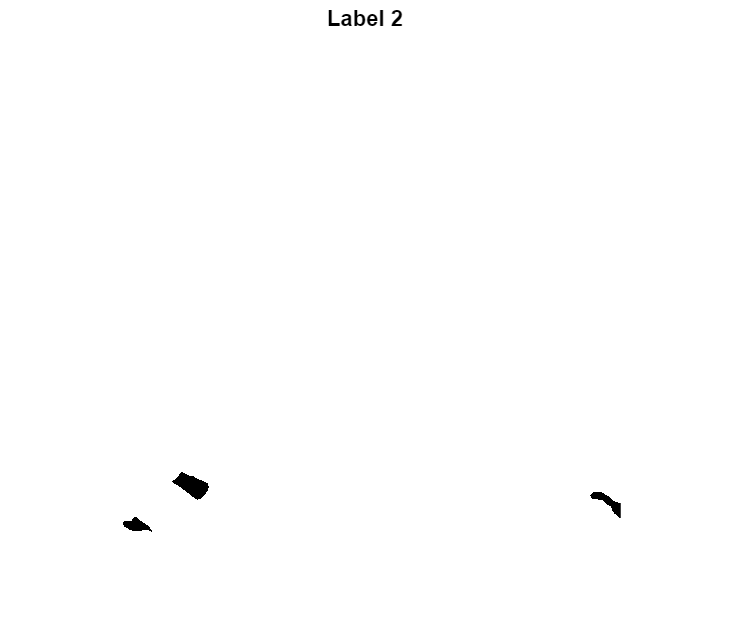

img_2_bw = img_2_gray < 20; % Adjust threshold - keep only black regions (binary mask)

% Make landlsides more pronounced
se_v1 = strel("disk",5);
img_2_bw_dilate = imdilate(img_2_bw, se_v1);

figure;
imshow(label_2);
title('Label 2');

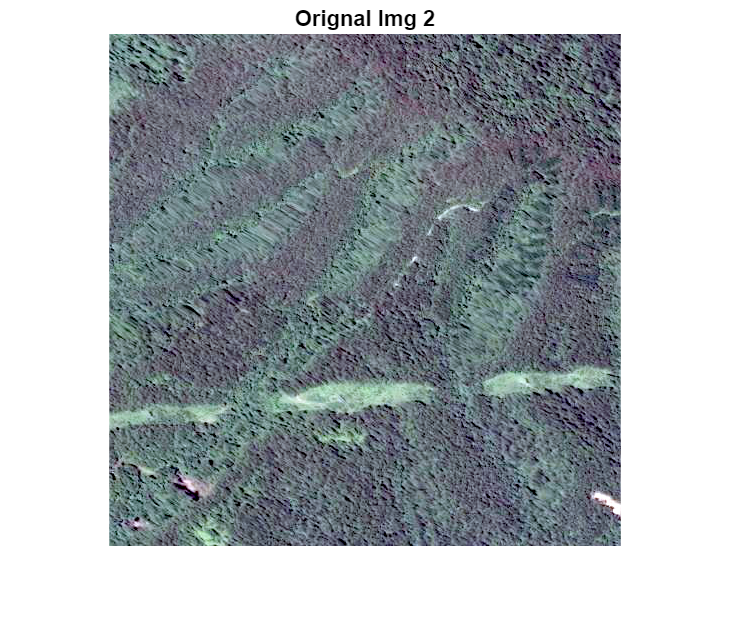

figure;
imshow(img_2);
title('Orignal Img 2');

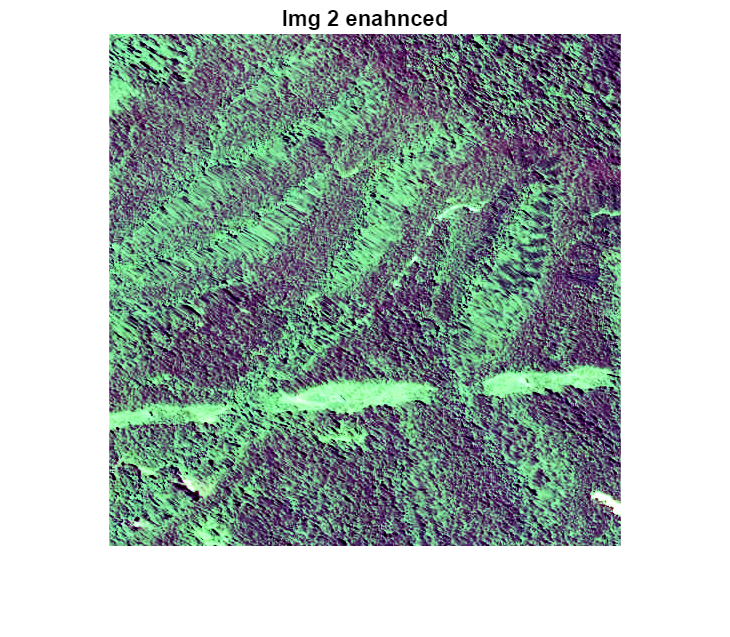

figure;
imshow(img_2_enhance_g);
title('Img 2 enahnced')

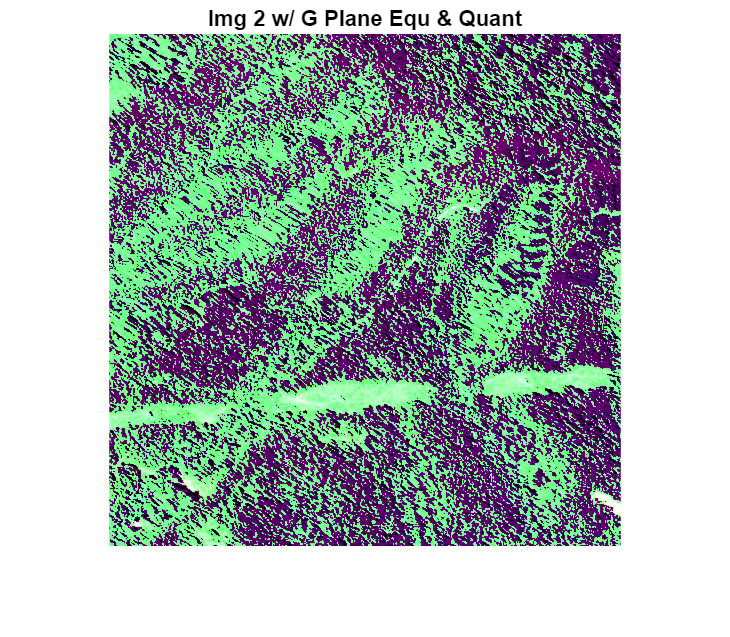

figure;
imshow(img_2_green_quant);
title('Img 2 w/ G Plane Equ & Quant');

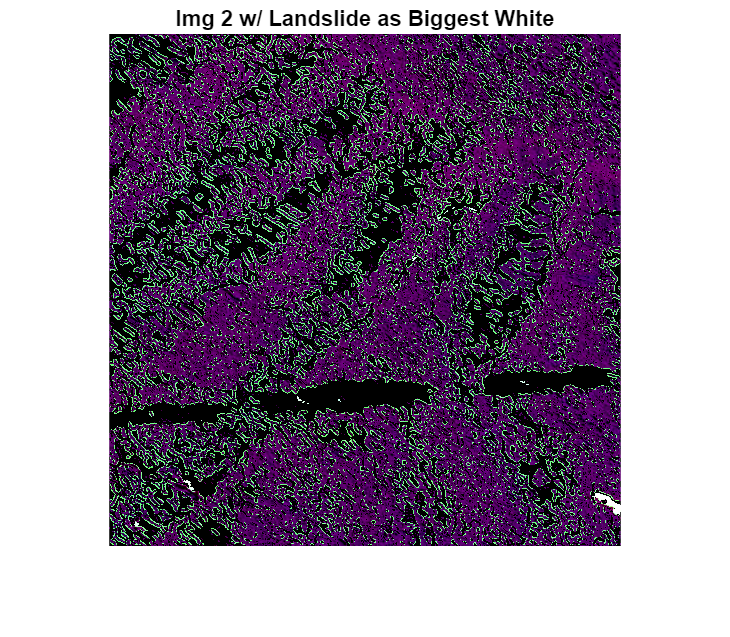

figure;
imshow(img_2_no_green);
title('Img 2 w/ Landslide as Biggest White');

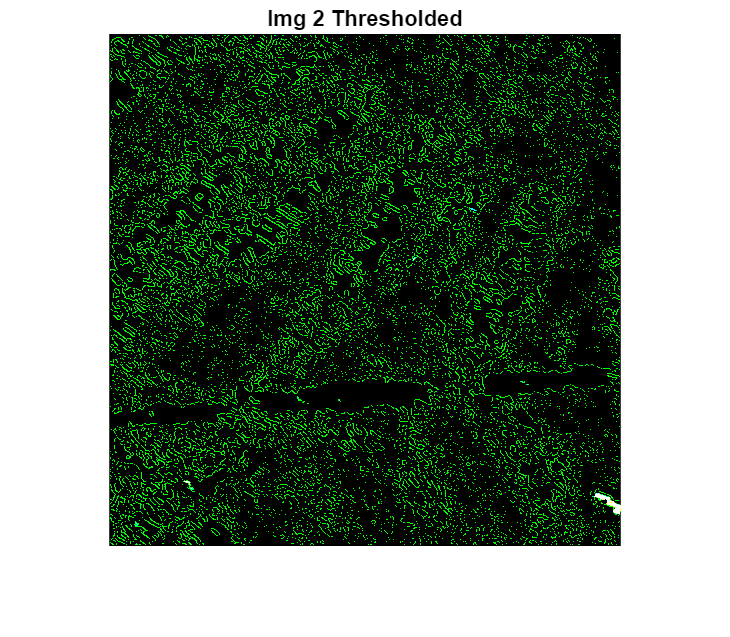

figure;
imshow(img_2_thresh);
title('Img 2 Thresholded');

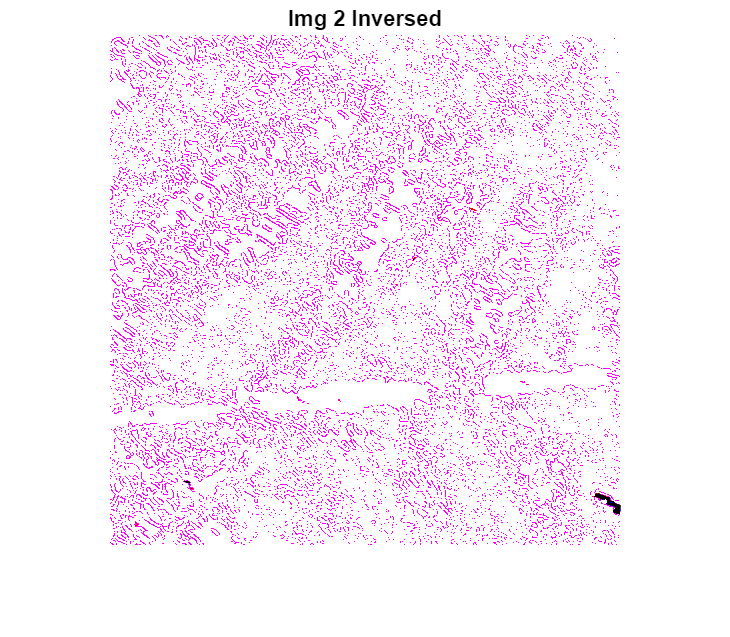

figure;
imshow(img_2_inv);
title('Img 2 Inversed');

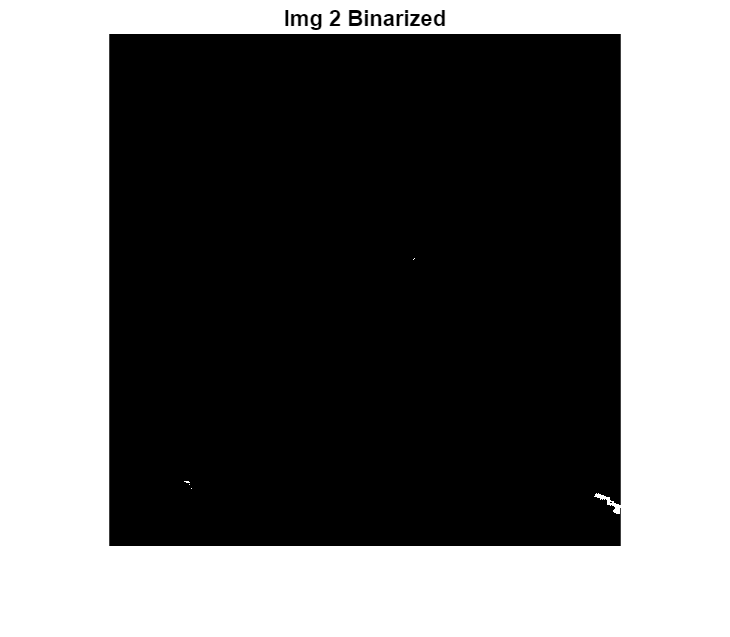

figure;
imshow(img_2_bw);
title('Img 2 Binarized');

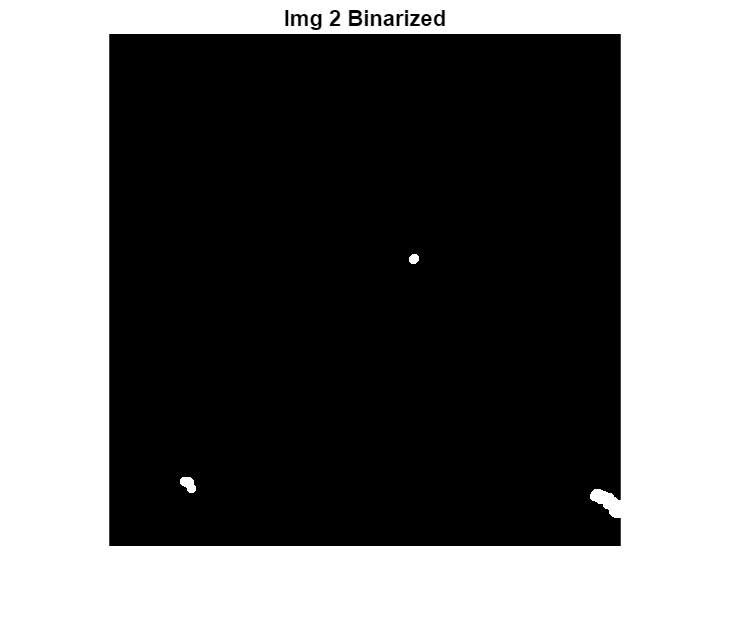

figure;
imshow(img_2_bw_dilate);
title('Img 2 Binarized');

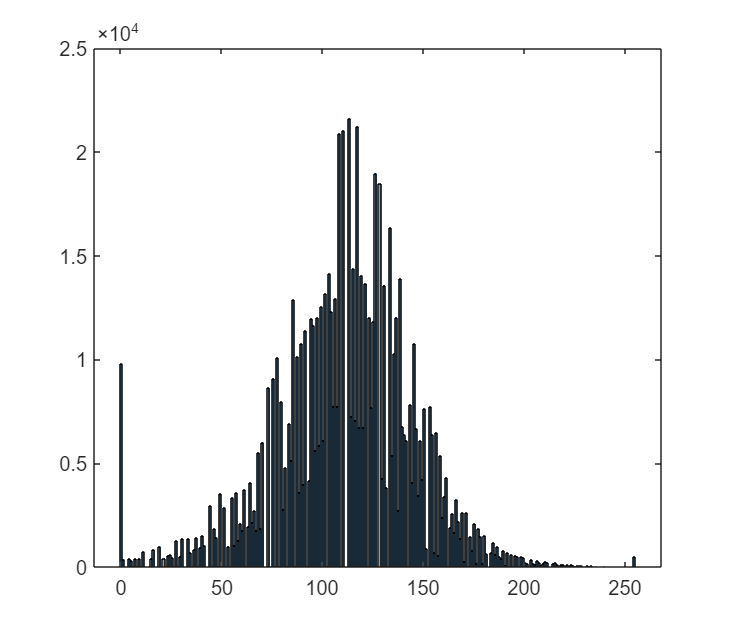



histogram(img_2);

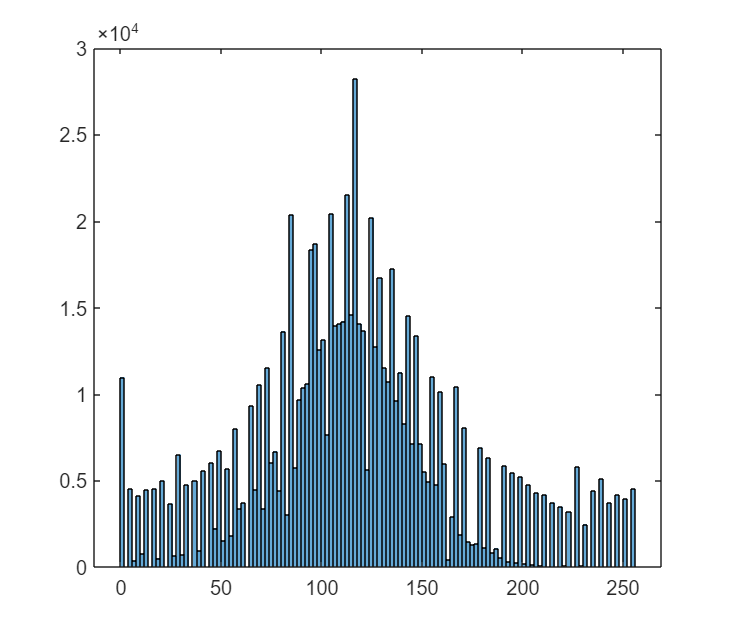

histogram(img_2_enhance_g);

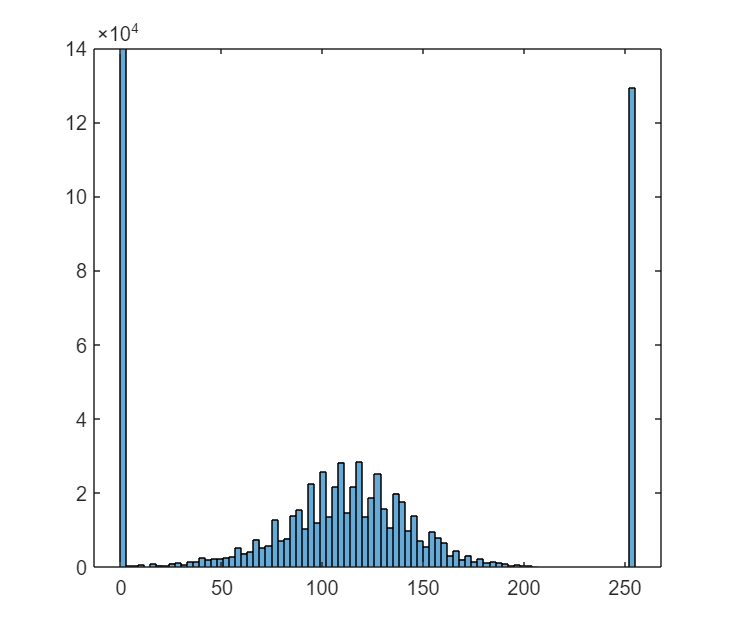

histogram(img_2_green_quant);

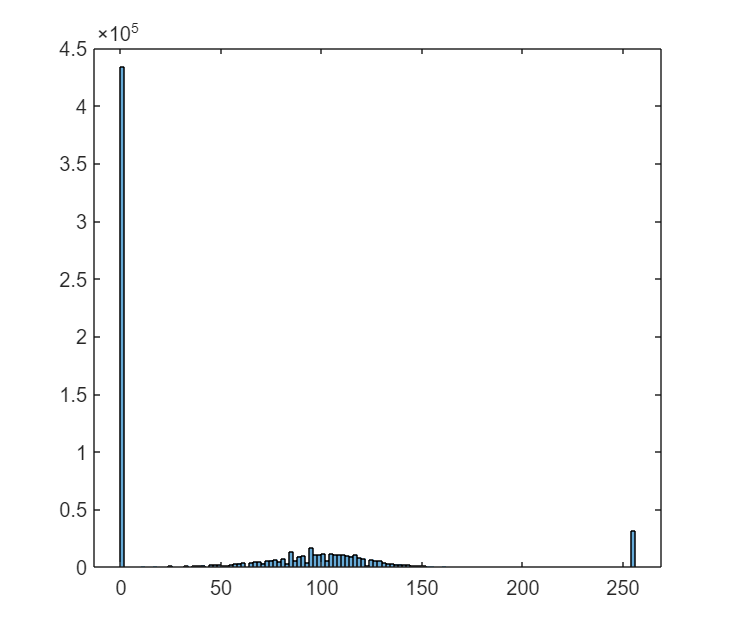

histogram(img_2_no_green);

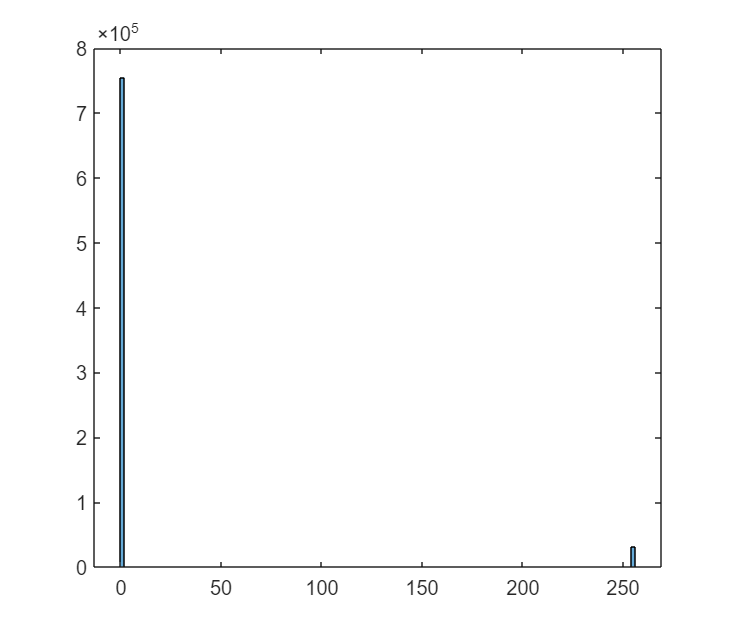

histogram(img_2_thresh);

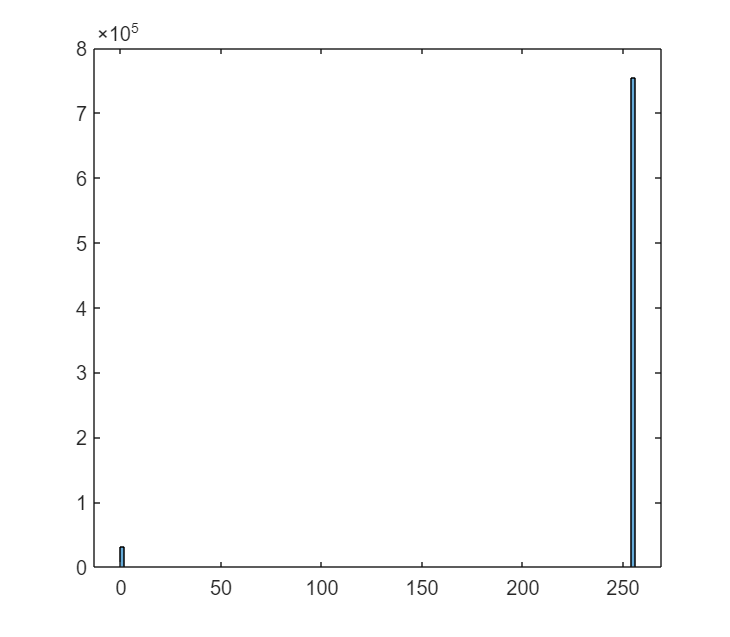

histogram(img_2_inv);

clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)

imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files=dir(label_directory)

labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


imgs = zeros(512,512,3,18,'uint8');
labels = zeros(512,512,3,18,'uint8');
for i=3:20
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)

ans =    512   512     3    18


size(labels)

ans =    512   512     3    18


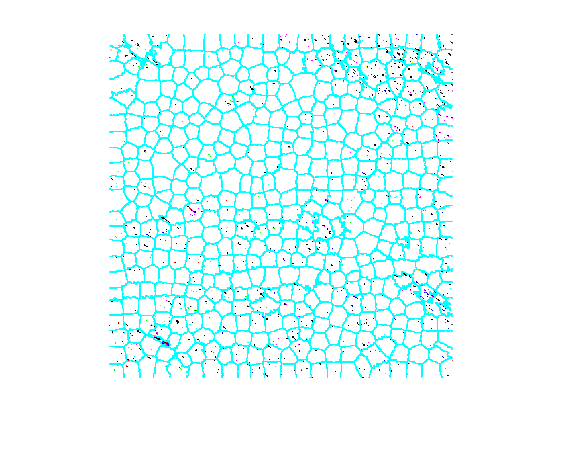


img_2 = double(imgs(:,:,:,2));
label_2 = labels(:,:,:,2);

% Calculate img superpixels
[L,N] = superpixels(img_2,500);
BW = boundarymask(L); % Superpixel boundaries
figure;
imshow(imoverlay(img_2,BW,'cyan'),'InitialMagnification',67); % Superpixel boundaries overlaid on orig img

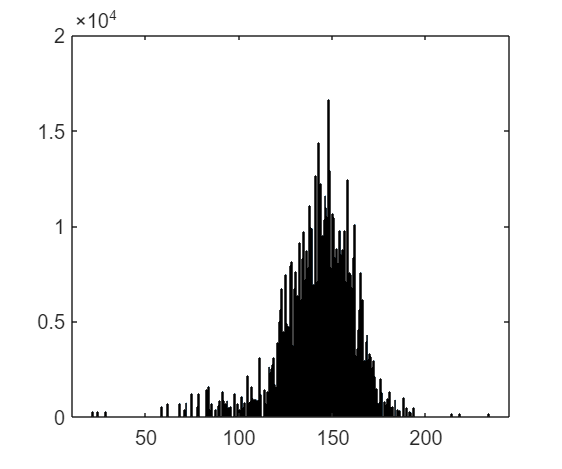

img_2_analysed = zeros(size(img_2),'like',img_2);
idx = label2idx(L);
num_rows = size(img_2,1);
num_cols = size(img_2,2);
for label_val = 1:N
    red_idx = idx{label_val};
    green_idx = idx{label_val}+num_rows*num_cols;
    blue_idx = idx{label_val}+2*num_rows*num_cols;
    img_2_analysed(red_idx) = mean(img_2(red_idx));
    img_2_analysed(green_idx) = mean(img_2(green_idx));
    img_2_analysed(blue_idx) = mean(img_2(blue_idx));
end    

histogram(255-img_2_analysed);

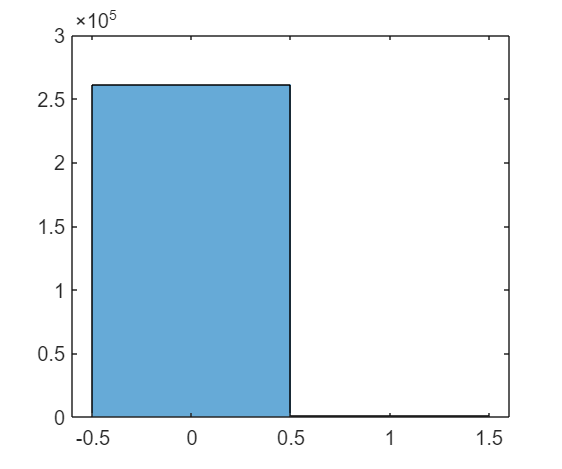

img_2_analysed_thresh = img_2_analysed;
img_2_analysed_thresh(img_2_analysed_thresh<195) = 0;
img_2_analysed_gray = rgb2gray(img_2_analysed_thresh);
histogram(img_2_analysed_gray);

img_2_analysed_bw = img_2_analysed_gray;
img_2_analysed_bw(img_2_analysed_bw<100) = 0;

figure;
imshow(img_2_analysed,'InitialMagnification',67);

figure;
montage([img_2_analysed(:,:,1),img_2_analysed(:,:,2),img_2_analysed(:,:,3)]);

figure;
montage([255-img_2_analysed(:,:,1),255-img_2_analysed(:,:,2),255-img_2_analysed(:,:,3)]);

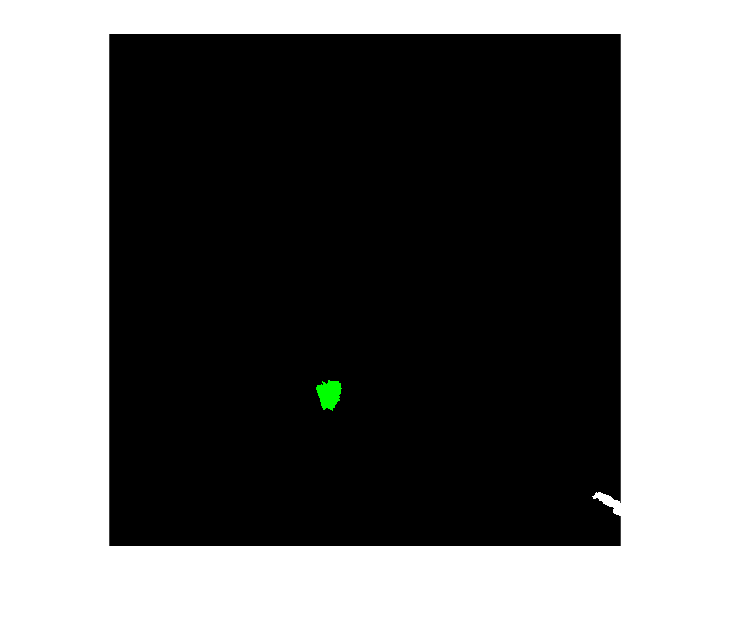

figure;
imshow(img_2_analysed_thresh);

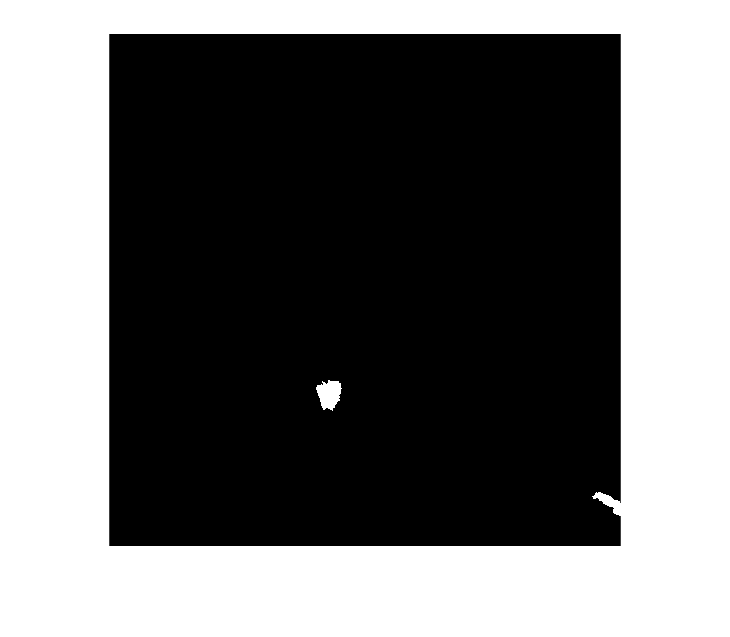

figure;
imshow(img_2_analysed_gray);

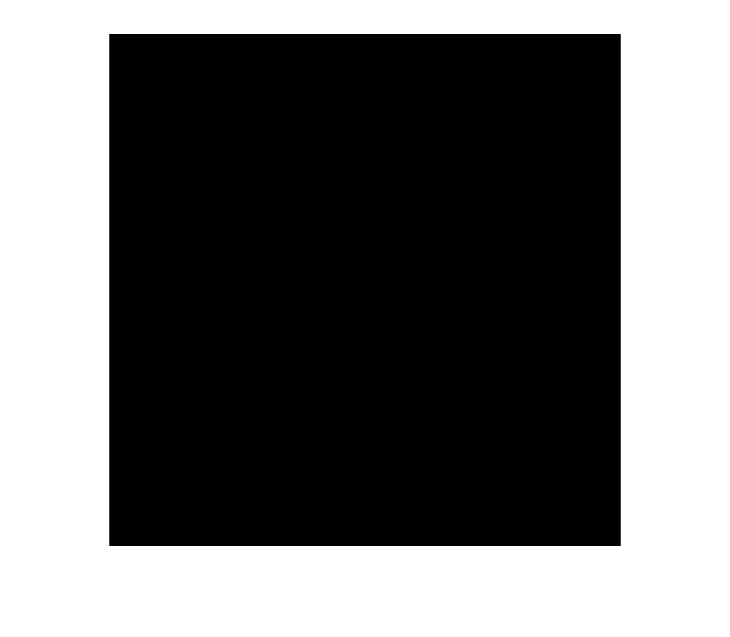

figure;
imshow(img_2_analysed_bw);

% stats = regionprops(img_2_bw_dilate, 'Area', 'Perimeter', 'Eccentricity', 'Solidity');
% 
% % Convert stats to feature matrix
% features = [stats.Area; stats.Perimeter; stats.Eccentricity; stats.Solidity]';
% 
% disp(features); % Extracted features
% 
% % Assume features is feature matrix extracted from multiple images & labels is vector (1 = landslide, 0 = no)
% 
% % Train SVM model
% SVMModel = fitcsvm(features, labels);
% 
% % Extract features from new image
% new_features = [new_stats.Area, new_stats.Perimeter, new_stats.Eccentricity, new_stats.Solidity];
% 
% % Predict if it's a landslide (1) or not (0)
% prediction = predict(SVMModel, new_features);
% 
% if prediction == 1
%     disp('Landslide detected!');
% else
%     disp('No landslide detected.');
% end